# Programming Practice

## BMED/ECE 4783, BMED/ECE 6780

## **Medical Image Processing**

**Spring 2021**

**Instructor: Prof. May D. Wang**

**Student Name: CHRISTINE SAW (gtID 903367317)**

Instructions: This is a take-home programing practical assignment. This assignment needs to be finished individually. DO NOT WORK WITH OTHERS ON THIS ASSIGNMENT! This assignment takes 5-10 hours to complete. Please plan accordingly.

Please list your required packages below the dash line!

-------------------------------------------------------------------------------

(Packages here)

### **Question 1.**

a. Generate a colored image using MATLAB/Python code similar to the one shown in figure below. Use following specifications.

`    i. Image size = 256x256 pixels`

`    ii. Image type = rgb`

`    iii. Circle radius = 25 pixels`

Sample image:

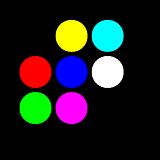

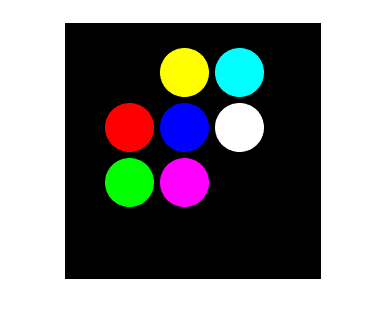

%% question 1 a, create similar image to sample image

% create black background, size 256 x 256
background = zeros([256 256 3]);
imshow(background);
hold on

% create array of angles to plot circle in polar coordinates later
th = 0:pi/50:2*pi;

% determine radius of circle (25 pixels)
r = 25;

% create yellow circle
x_circle = r * cos(th) + 120; % 120 is x-coordinate of the circle's center
y_circle = r * sin(th) + 50; % 50 is y-coordinate of the circle's center
plot(x_circle, y_circle); % plot the circle 
fill(x_circle, y_circle, 'y') % fill circle with color

% create cyan circle
x_circle = r * cos(th) + 175;
y_circle = r * sin(th) + 50;
plot(x_circle, y_circle);
fill(x_circle, y_circle, 'c')

% create red circle
x_circle = r * cos(th) + 65;
y_circle = r * sin(th) + 105;
plot(x_circle, y_circle);
fill(x_circle, y_circle, 'r')

% create blue circle
x_circle = r * cos(th) + 120;
y_circle = r * sin(th) + 105;
plot(x_circle, y_circle);
fill(x_circle, y_circle, 'b')

% create white circle
x_circle = r * cos(th) + 175;
y_circle = r * sin(th) + 105;
plot(x_circle, y_circle);
fill(x_circle, y_circle, 'w')

% create green circle
x_circle = r * cos(th) + 65;
y_circle = r * sin(th) + 160;
plot(x_circle, y_circle);
fill(x_circle, y_circle, 'g')

% create purple/magenta circle
x_circle = r * cos(th) + 120;
y_circle = r * sin(th) + 160;
plot(x_circle, y_circle);
fill(x_circle, y_circle, 'm')

% save created image into computer as png file
F = getframe(gca);

imwrite(F.cdata, 'color_image.png');


b. Display r, g and b planes separately from the image in problem 1. Convert this image to HSI (HSV) color space and display 3 different planes. Sample results are shown without labeling. Your solution must be labeled.

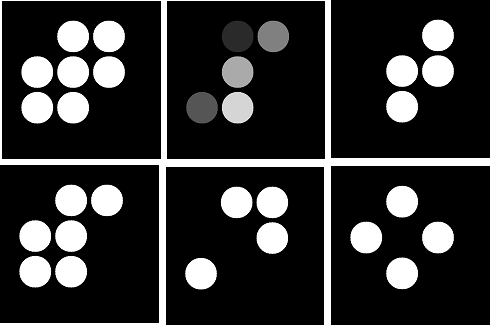

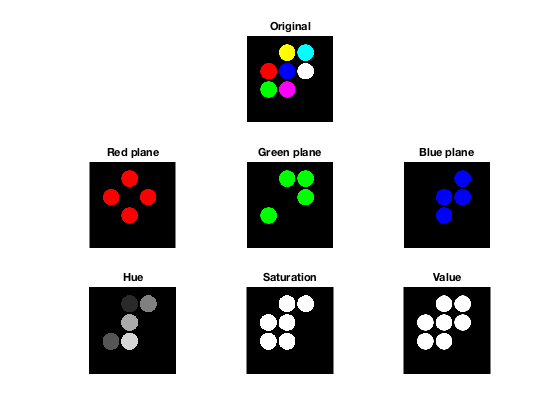

%% question 1 b, separating image into rgb and hsv planes

% read the rgb color image generated from question 1 a
image = imread('color_image.png'); 

% extract red, green, and blue channels
red = image(:,:,1); % Red channel
green = image(:,:,2); % Green channel
blue = image(:,:,3); % Blue channel

% create an all black channel (a.k.a. black background)
black = zeros(size(image, 1), size(image, 2));

% create colored versions of color channels for aesthetic purposes
just_red = cat(3, red, black, black);
just_green = cat(3, black, green, black);
just_blue = cat(3, black, black, blue);

% convert rgb image into hsv
hsv = rgb2hsv(image);

% extract hue, saturation, and value planes
hue = hsv(:,:,1); % Hue plane
saturation = hsv(:,:,2); % Saturation plane
color = hsv(:,:,3); % Value plane

figure;
% display original image, rgb, and hsv plane images
subplot(3,3,2); imshow(image); title('Original');
subplot(3,3,4); imshow(just_red); title('Red plane');
subplot(3,3,5); imshow(just_green); title('Green plane')
subplot(3,3,6); imshow(just_blue); title('Blue plane')
subplot(3,3,7);imshow(hue);title('Hue');
subplot(3,3,8);imshow(saturation);title('Saturation');
subplot(3,3,9);imshow(color);title('Value');

### **Question 2.**

a. Select the Hue image from problem-1 and convert to grayscale. Add “Salt and Pepper” noise to it and add random noise to this image in form of 200 pixels of random intensity and random location. Using a 5x5 Gaussian kernel and 5x5 averaging kernel to remove the noise, display noisy as well as cleaned images and compare the performance of the two filters.

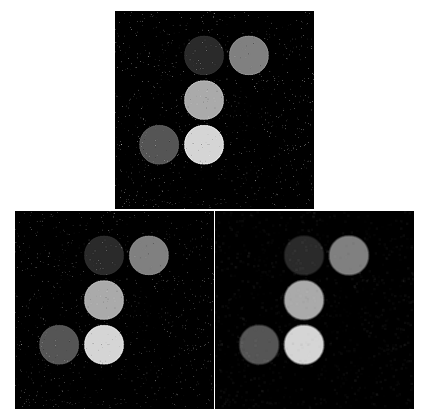

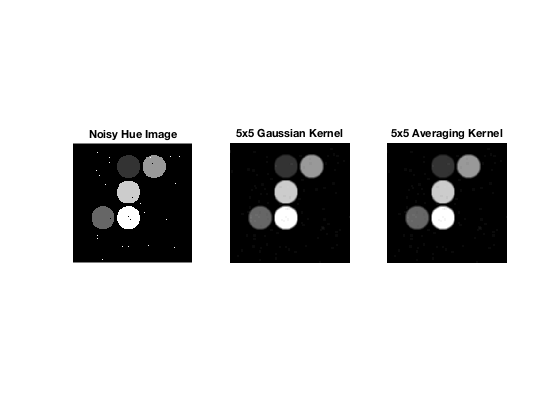

%% question 2 a, convert hue image into grayscale + add filter noise

% convert hue plane image (generated from question 1 b) to grayscale
grey_hue = mat2gray(hue);

% generate salt and pepper noise in grayscaled hue image
% determine noise density
d = 200/numel(grey_hue);
% since the given noise condition was to add 200 pixels of random noise,
% the noise density, d, was chosen such that:
% d * (total pixels in image) = 200 pixels of noise
noisy_hue = imnoise(grey_hue,'salt & pepper',d); 

% filter image using 5x5 gaussian kernel
% sigma value of 5 was arbitrarily chosen
gaussian_image = imgaussfilt(noisy_hue,5,'FilterSize',5);

% create 5x5 averaging filter
avg_h = fspecial('average',5);
% filter noisy image using 5x5 averaging filter
avg_image = imfilter(noisy_hue,avg_h);

figure;
% display noisy image and filtered images
subplot(1,3,1);imshow(noisy_hue);title('Noisy Hue Image');
subplot(1,3,2);imshow(gaussian_image);title('5x5 Gaussian Kernel');
subplot(1,3,3);imshow(avg_image);title('5x5 Averaging Kernel');

**Comparison of performance of two filters**

Both the gaussian and averaging filters produce very similar results. 

The noise look less obvious compared to the original noisy image.

Both filters managed to filter the noise out from the noisy image.

However, both filtered images result in a blurrer image when compared to the original noisy image.

The circles in the filtered image have blurrer edges when compared to the original noisy image.

b. Edge detection Convert the colored image created in 1(a) into grayscale image. Apply following kernels for edge detection to find the outlines of the diamonds in the figure.

`    i.Sobel `

`    ii.Prewitt `

`    iii.Canny`

Which method gives best result and why? How can you improve the performance of other edge detectors?

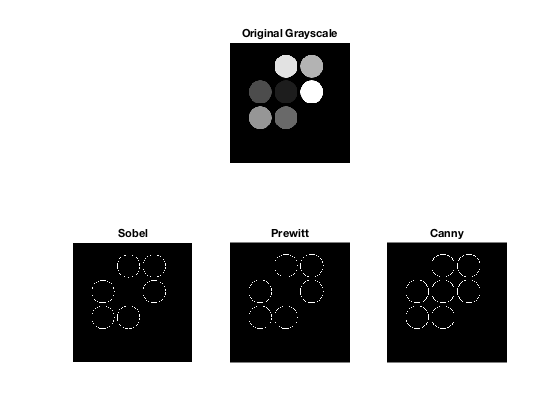

%% question 2 b, edge detection - using kernels to detect edges of circles

% read the rgb color image generated from question 1 a
image = imread('color_image.png'); 

% convert original color image into grayscale
grey_image = rgb2gray(image);

% (i) Sobel kernel for edge detection with MATLAB edge.m function
sobel_image = edge(grey_image,'Sobel');

% (ii) Prewitt kernel using MATLAB edge.m function
prew_image = edge(grey_image,'Prewitt');

% (iii) Canny kernel using MATLAB edge.m function
canny_image = edge(grey_image,'Canny');

figure;
% display grayscale image and filtered images
subplot(2,3,2);imshow(grey_image);title('Original Grayscale')
subplot(2,3,4);imshow(sobel_image);title('Sobel');
subplot(2,3,5);imshow(prew_image);title('Prewitt');
subplot(2,3,6);imshow(canny_image);title('Canny');

Write your answer below this dashed line!

----------------------------------------------------------

The Canny method performed the best, successfully detecting all edges. 

Both the Sobel and Prewitt methods only find edges at points where the gradient of the image is maximum, by using Sobel and Prewitt deritatives respectively. 

The Canny method works by looking for the local maxima of the gradient of the image, and then calculates the gradient using the deritative of a Gaussian filter. The Canny method uses two methods to detect strong and weak edges. It includes weak edges if they are connected to the strong edges. 

The Canny method identifies two thresholds, therefore, it has an advantage over Sobel and Prewitt.

We can improve the performance of other edge detectors by setting the threshold levels lower, although this may increase the thickness of the edges, it will allow us to detect more edges.

### **Question 3.**

a. The white bars in the pattern shown below are 7 pixels wide and 210 pixels high. The separation between bars is 17 pixels. What would this image look like after application of 

- A 3 x 3 arithmetic mean filter?

- A 5 x 5 arithmetic mean filter?

- A 7 x 7 arithmetic mean filter?

- Note that the above three operations are independently done on the original image.

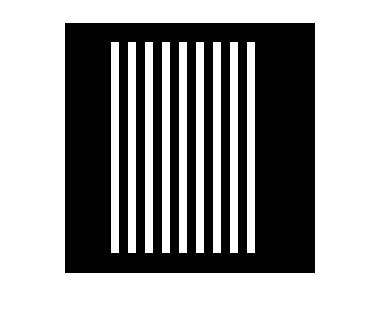

% Draw your original pattern here
figure;
image_size = 250;
bar_rol = 20;
bar_col = 30;
bar_height = 210;
bar_width = 7;
separatedby = 17;

img = zeros(250);
for i = 1:9
    img(bar_rol:bar_rol+bar_height, bar_col+i*separatedby:bar_col+i*separatedby+bar_width) = 1;
end
imshow(img)

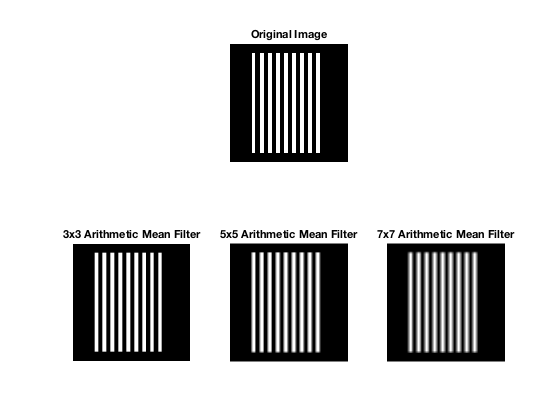

%% question 3 a, applying various arithmetic mean filters on an image

% first, generate image like in assignment question 3 a
% code given in assignment
image_size = 250;
bar_rol = 20;
bar_col = 30;
bar_height = 210;
bar_width = 7;
separatedby = 17;

img = zeros(250);
for i = 1:9
    img(bar_rol:bar_rol+bar_height, bar_col+i* ...
    separatedby:bar_col+i*separatedby+bar_width) = 1;
end
% imshow(img)

% (i) use 3x3 arithmetic mean filter to filter image
mean_3 = imfilter(img,fspecial('average',3));
% all white lines' edges look a little blurry compared to original

% (ii) use 5x5 arithmetic mean filter to filter image
mean_5 = imfilter(img,fspecial('average',5));
% edges of white lines start to look more gray compared to original

% (iii) use 7x7 arithmetic mean filter to filter image
mean_7 = imfilter(img,fspecial('average',7));
% the edges are blurry and any visible white lines look comparably thinner
% as the white lines are almost grayed out due to blurring from filter

figure;
% display original image with filtered images
subplot(2,3,2);imshow(img);title('Original Image');
subplot(2,3,4);imshow(mean_3);title('3x3 Arithmetic Mean Filter');
subplot(2,3,5);imshow(mean_5);title('5x5 Arithmetic Mean Filter');
subplot(2,3,6);imshow(mean_7);title('7x7 Arithmetic Mean Filter');

**Image analysis after applying filters:**

3x3 arithmetic mean filter: all white lines' edges look a little blurry compared to original

5x5 arithmetic mean filter: edges of white lines start to look more gray and blurred out compared to original

7x7 arithmetic mean filter: the edges are blurry and any visible white lines look comparably thinner as the white lines are almost grayed out due to blurring from the filter

b. Repeat Problem 3(a) using a median filter.

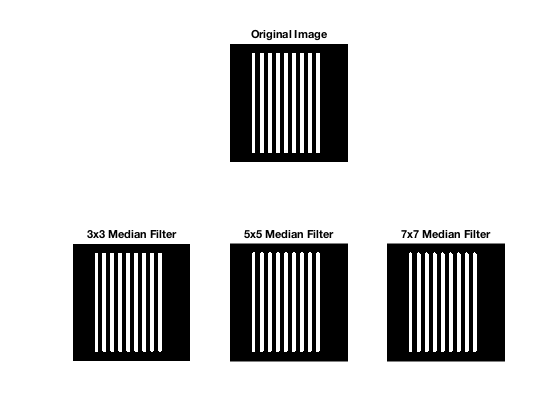

%% question 3 b, applying median filters on an image

% (i) 3x3 median filter
med_3 = medfilt2(img,[3 3]);
% the corners of the white lines look a little rounded

% (ii) 5x5 median filter
med_5 = medfilt2(img,[5 5]);
% the top and bottom edges of the white lines are no longer straight, 
% they are visibly rounded on the top and bottom edges

% (iii) 7x7 median filter
med_7 = medfilt2(img,[7 7]);
% the white lines are rounded on the top and bottom edges, and have a
% sharper looking roundedness when compared with the 5x5 median filter

figure;
% display original image with filtered images
subplot(2,3,2);imshow(img);title('Original Image');
subplot(2,3,4);imshow(med_3);title('3x3 Median Filter');
subplot(2,3,5);imshow(med_5);title('5x5 Median Filter');
subplot(2,3,6);imshow(med_7);title('7x7 Median Filter');

**Image analysis after applying filters:**

3x3 median filter: the corners of the white lines look a little rounded

5x5 median filter: the top and bottom edges of the white lines are no longer straight, they are visibly rounded on the top and bottom edges

7x7 median filter: the white lines are rounded on the top and bottom edges, and have a sharper looking roundedness when compared with the 5x5 median filter

c. Repeat Problem 3(a) using a max filter.

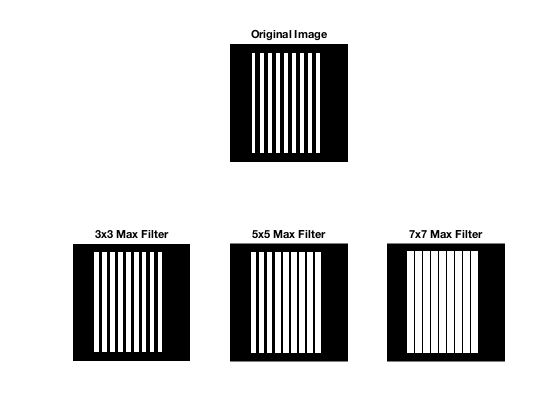

%% question 3 c, applying max filters on an image

% (i) 3x3 max filter
max_3 = ordfilt2(img,9,true(3));
% the white lines look slightly thicker

% (ii) 5x5 max filter
max_5 = ordfilt2(img,25,true(5));
% the white lines are visibly thicker compared to the 3x3 max filter

% (i) 7x7 max filter
max_7 = ordfilt2(img,49,true(7));
% the white lines look doubled in width, and have the thickest width
% compared to the other filters, the black gaps are barely visible

figure;
% display original image with filtered images
subplot(2,3,2);imshow(img);title('Original Image');
subplot(2,3,4);imshow(max_3);title('3x3 Max Filter');
subplot(2,3,5);imshow(max_5);title('5x5 Max Filter');
subplot(2,3,6);imshow(max_7);title('7x7 Max Filter');

**Image analysis after applying filters:**

3x3 max filter: the white lines look slightly thicker

5x5 max filter: the white lines are visibly thicker compared to the 3x3 max filter

7x7 max filter: the white lines look doubled in width, and have the thickest width compared to the other filters, the black gaps are barely visible

### **Question 4. **

**In this problem, we will compare the capability of discrete cosine transform (DCT) and discrete Fourier transform (DFT), in capturing the information in image blocks. The purpose of transform is to reduce the total number of bytes for storage space. (Hint: for the “zero-valued” coefficients in the transform domain, you only need 1 bit for each pixel.)**

a. Please use the provided image “Cameraman128.bmp” for this problem. First, divide the image into 16x16 sub-images or blocks. The original image is of size 128x128, so there will be total 64 blocks. Apply 2-D discrete cosine transform (DCT) on each block. (Hint: MATLAB inbuilt function-dct2; Python: scipy.fftpack.dct). For each block, only retain most informative 25% DCT coefficients, with high magnitude, and truncate the rest 75% coefficients to zero. Apply inverse DCT transform on the truncated DCT coefficients for each block to recover original block image (MATLAB -idct2). Stitch the recovered block images to recover the original image. You ONLY need to show the final stitched inverse DCT image and the difference image.

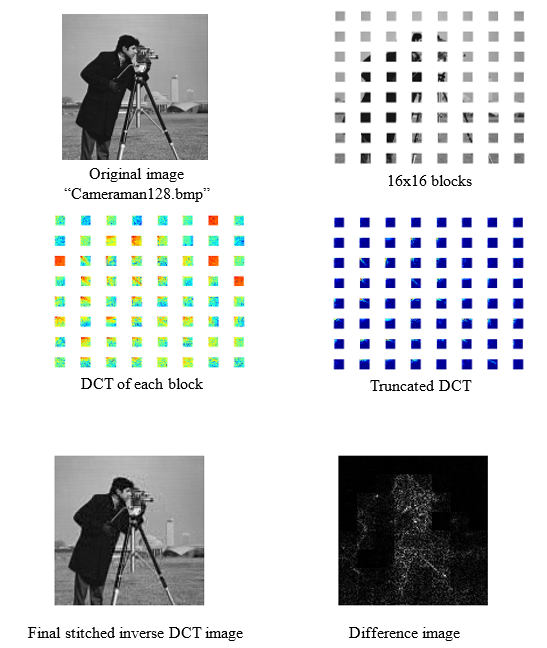

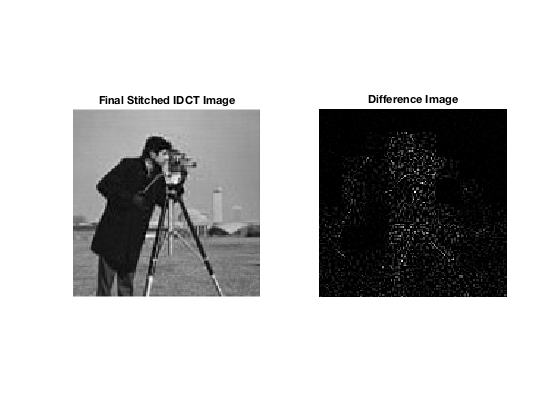

%% question 4 a, using DCT to reduce image bytes
% split img, DCT, truncate img, inverse DCT, stitch img

% read cameraman image into MATLAB
cameraman = imread('Cameraman128.bmp');

% read number of rows, columns and color bands from image
[c_rows,c_columns,numberOfColorBands] = size(cameraman);

% we want to get 16x16 blocks -> 16 pixels per row & column per block
block_size = 16;

% if we have 16x16 blocks, image will be split into 64 sub-images 
% each row and column will have 8 sub-images
% create vector of length 8 that contains the size for the sub-images'
% rows' or columns' pixels -> [16,16,16,...]
vectorRC = block_size * ones(1, 8);

% split cameraman image into 64 16x16 sub-images 
sub_images = mat2cell(cameraman, vectorRC, vectorRC, numberOfColorBands);

% number of sub-images per row and per column
num_plots_rc = 8;

% create cell to store truncated sub-images
dct_sub = cell(8,8);

% perform DCT, truncation, and IDCT on sub-images
for r = 1 : num_plots_rc
    for c = 1 : num_plots_rc
        
        % convert each block into double and grayscale to get 2-D image
        blk = rgb2gray(im2double(sub_images{r,c}));
        
        % perform dct on each block
        J = dct2(blk);
        
        % arrange absolute value of coefficients from highest to lowest
        J_desc = sort(abs(J(:)),'descend');  
        
        % get top 25% coefficients with highest magnitudes
        top25 = J_desc(1:ceil(length(J_desc)*0.25));  

        % change remaining 75% lower coefficients to 0
        J(abs(J) < min(top25)) = 0;
        
        % perform inverse DCT on truncated sub-image
        K = idct2(J);
        
        % convert double to uint8 
        K = uint8(255 * K);
        
        % store IDCT truncated sub-image into cell
        dct_sub{r,c} = K;
    end
end

% restitch truncated sub-images into single image
dct_image = [];
for r = 1 : num_plots_rc
    % create empty array to store each row of sub-images
    image_rows = [];
    
    for c = 1 : num_plots_rc
        % combine sub-images in a row (combine sub-images horizontally)
        image_rows = [image_rows,dct_sub{r,c}];
    end
    
    % combine sub-images vertically
    dct_image = [dct_image;image_rows];
end

% create cell to store difference sub-images
diff_dct_sub = cell(8,8);
% array to store stitched difference image
diff_dct_image = [];
% compute difference between original and truncated IDCT image
% and stitch difference blocks into full image
for r = 1 : num_plots_rc
    % create empty array to store each row of sub-images
    diff_rows = [];
    
    for c = 1 : num_plots_rc
        % compute difference between original and truncated IDCT image
        diff_dct_sub{r,c} = abs(rgb2gray(sub_images{r,c}) - dct_sub{r,c});
        % combine sub-images in a row (combine sub-images horizontally)
        diff_rows = [diff_rows,diff_dct_sub{r,c}];
    end
    
    % combine sub-images vertically
    diff_dct_image = [diff_dct_image;diff_rows];
end

figure;
% display truncated IDCT image and difference image
subplot(1,2,1);imshow(dct_image);title('Final Stitched IDCT Image');
subplot(1,2,2);imshow(mat2gray(diff_dct_image));title('Difference Image');

b. (40 points) Repeat steps (ii) and (v) in part (a) with discrete Fourier transform (fft2 and ifft2 in MATLAB).

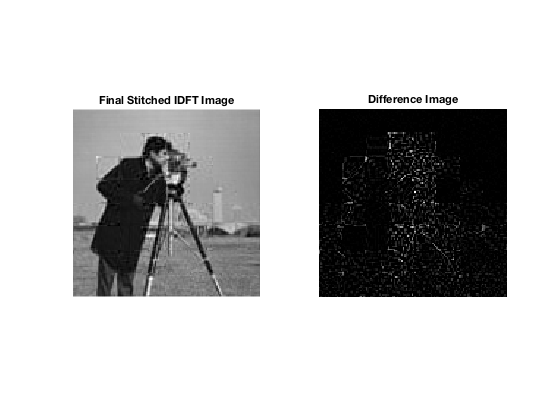

%% question 4 b, using DFT to reduce image bytes
% split image, perform DFT, truncate image, inverse DFT, then stitch image

% we can reuse the sub-images generated from question 4 a

% create cell to store truncated sub-images
fft_sub = cell(8,8);

% perform DFT, truncation, and IDFT on sub-images
for r = 1 : num_plots_rc
    for c = 1 : num_plots_rc
        
        % convert each block into double then grayscale to get 2-D image
        blk = rgb2gray(im2double(sub_images{r,c}));
        
        % perform dft on each block
        J = fft2(blk);
        
        % arrange absolute value of coefficients from highest to lowest
        J_desc = sort(abs(J(:)),'descend');  
        
        % get top 25% coefficients with highest magnitudes
        top25 = J_desc(1:ceil(length(J_desc)*0.25));  

        % change remaining 75% lower coefficients to 0
        J(abs(J) < min(top25)) = 0;
        
        % inverse DFT truncated sub-image
        K = ifft2(J);
        
        % convert double to uint8 
        K = uint8(255 * K);
        
        % store IDFT truncated sub-image into cell
        fft_sub{r,c} = K;
    end
end

% restitch truncated sub-images into single image
fft_image = [];
for r = 1 : num_plots_rc
    % create empty array to store stitched sub-images in a row
    image_rows = [];
    
    for c = 1 : num_plots_rc
        % combine sub-images in a row (combine sub-images horizontally)
        image_rows = [image_rows,fft_sub{r,c}];
    end
    
    % combine sub-images vertically
    fft_image = [fft_image;image_rows];
end

% create cell to store difference between original and truncated blocks
diff_fft_sub = cell(8,8);
% array to store stitched difference image
diff_fft_image = [];
% compute difference between original and truncated IFFT image
% and stitch difference blocks into full image
for r = 1 : num_plots_rc
    % create empty array to store stitched sub-images in a row
    diff_rows = [];
    
    for c = 1 : num_plots_rc
        diff_fft_sub{r,c} = abs(rgb2gray(sub_images{r,c}) - fft_sub{r,c});
        % combine sub-images in a row (combine sub-images horizontally)
        diff_rows = [diff_rows,diff_fft_sub{r,c}];
    end
    
    % combine sub-images vertically
    diff_fft_image = [diff_fft_image;diff_rows];
end

figure;
% display truncated IDFT image and difference image
subplot(1,2,1);imshow(fft_image);title('Final Stitched IDFT Image');
subplot(1,2,2);imshow(mat2gray(diff_fft_image));title('Difference Image');

c. (20 points) What differences do you observe in the results from DCT and DFT? Which method would you prefer to use for reducing total number of bytes for storage space? Try to justify.

Write your answer below the dashed line!

----------------------------------------------------------------

DFT managed to compress the image more than DCT, however it got rid of too much information from the blocks, such that the restitched image did not look as smooth as the restitched IDCT image.

I would prefer using DCT, as the restitched image was smoother. I would like a good balance between taking up less bytes and having a smooth resolution.

While DFT managed to compress the image better, it didn't retain enough information to produce a smooth IDFT image. 

The restitched IDCT image retains just enough information for us to make sense of the original picture while taking up less bytes than the original.